# Part B)

## i)

% function [xyso,F]=Report_Part_B(key_filename)
% fID=fopen(key_filename);
% %reading number of keypoints
% K=fscanf(fID,'%d',[1 1]);
% fscanf(fID,'%d',[1 1]);
% xyso=nan(K,4);
% F=nan(K,128);
% for i=1:K
%     %reading xyso
%     xyso(i,:)=fscanf(fID,'%f',[1 4]);
%     %reading feature
%     F(i,:)=fscanf(fID,'%d',[1 128]);
% end
% fclose(fID);
% end

## ii)

% function D=pairwise_distance(F1,F2)
% [r1,~]=size(F1);
% [r2,~]=size(F2);
% D=nan(r1,r2);
% for i=1:r1
%     for j=1:r2
%         D(i,j)=sqrt(sum((F1(i,:)-F2(j,:)).^2));
%     end
% end
% end

## iii)

% function P=paired_keypoints(D,thresh)
% s=size(D);
% P=zeros(s(1),1);
% for i=1:s(1)
%     d=[D(i,:);1:s(2)]';
%     d=sortrows(d);
%     if (d(1,1)/d(2,1))<thresh
%         P(i)=d(1,2);
%     end
% end
% end

## iv)

I=double(imread('cameraman.pgm'))/255;
I_t=imrotate(I,10,'crop');
imwrite(I_t,'I_t.pgm');
system('siftDemoV4\siftWin32 <cameraman.pgm>I.key')

Finding keypoints... 
336 keypoints found. 


ans = 0

system('siftDemoV4\siftWin32 <I_t.pgm>I_t.key')

Finding keypoints... 
324 keypoints found. 


ans = 0

[xyso,F]=create_feature_matrices('I.key');
[xyso_t,F_t]=create_feature_matrices('I_t.key');

disp('First row of xyso:')

First row of xyso:


disp(xyso(1,:))

  111.7100   86.7200   33.9900    2.4760




disp('First row of F:')

First row of F:


disp(F(1,:))

  Columns 1 through 30

     0     0     0     0     4     2     0     0    13    76     6     4    11     4     0     0    24    41     0     0     0     0     0     0     0     0     0     0     0     0

  Columns 31 through 60

     0     0     0     0     0     0    57    49     8     6   118   121    11     8   149   146    12    16   149   119     1     0     3     5     4    38    11     0     0     0

  Columns 61 through 90

     0     0     0     1     0     0     0     0    11    55    54    39    45     4     0     0    56   149   149   117   149    10     0     0     1    18    87   149     9     0

  Columns 91 through 120

     0     0     0     3     4     9     1     0     0     0     0     2     6     4    15     5     0     0     0    21    68    36     2     0     0     0     0     1    31    59

  Columns 121 through 128

     0     0     0     0     0     0     0     0




disp('First row of xyso_t:')

First row of xyso_t:


disp(xyso_t(1,:))

  116.8200   84.9900   30.5800    2.5140




disp('First row of F_t:')

First row of F_t:


disp(F_t(1,:))

  Columns 1 through 30

     0     0     0     0     8     9     0     0    31    16     4     0    16    10    10    21    46     4     0     0     0     0     7    41     0     0     0     0     0     0

  Columns 31 through 60

     0     0     8     0     0     0    54   102    11    14   137    50     3     0   113   143    23    32   143    67    10    22     1     4     8    66    12     5     7    29

  Columns 61 through 90

     0     0     0     0     4     3     1     0     7    62    60    53    36     7     1     0    22   143   143    68   143    16    13   101    61    44   114   109     3     2

  Columns 91 through 120

     7   127    39     1     0     0     1    15     5     0     0     1     4     4    17    78     7     0     0    17    66    10     3     3     0     2    18    34    45     5

  Columns 121 through 128

     0     0     0     2     6     1     0     0




D=pairwise_distance(F,F_t);

disp('First row of D:')

First row of D:


disp(D(1,:))

  Columns 1 through 18

  270.6123  507.5204  575.6501  519.2129  618.0526  606.0050  593.1475  540.5627  497.0523  543.0525  605.9299  618.4157  444.2522  419.8928  432.4697  562.1406  608.3190  528.7911

  Columns 19 through 36

  479.3183  451.6569  535.9655  568.6827  484.8979  418.7063  543.2154  535.4344  508.4201  584.6845  631.6423  553.6344  615.6744  594.2356  552.4228  571.4482  610.1393  531.0734

  Columns 37 through 54

  579.5835  535.7107  607.4669  555.5106  555.0919  577.2053  501.2355  641.1552  647.1885  636.4755  523.8177  624.6463  624.9288  614.4420  619.3755  573.7194  555.0513  453.0519

  Columns 55 through 72

  571.4735  555.0378  596.1283  583.5992  593.9495  530.7542  438.0594  597.9657  570.3727  565.2062  603.8982  609.8697  613.4843  565.8030  428.2698  574.0383  438.1906  587.9099

  Columns 73 through 90

  581.6502  414.6336  554.8423  584.2380  603.4940  565.1283  578.4384  406.1391  565.7747  580.2844  534.0721  529.7311  574.9643  605.7425  575.18


P=paired_keypoints(D,0.6);

disp('Matrix "P":')

Matrix "P":


disp(P)

     0
     0
     0
     9
    10
     0
    12
     0
    20
     0
     0
     0
    16
    18
    17
    19
    20
    21
    22
     0
    24
    25
    42
    26
    27
    28
    29
     0
    37
    35
     0
    41
    38
    40
    39
    43
    47
    49
    50
    51
    52
    53
    56
     0
     0
     0
     0
     0
    58
     0
     0
    61
     0
    60
    63
    62
    65
    66
    68
    69
    70
     0
    71
     0
     0
     0
     0
    74
    75
    80
    77
    81
    82
     0
     0
    88
    89
     0
    87
     0
     0
     0
    95
    96
     0
     0
     0
     0
     0
     0
     0
   103
   133
     0
   104
   101
   105
     0
     0
     0
     0
     0
   107
     0
     0
   110
   111
     0
    85
     0
   116
     0
     0
     0
     0
     0
     0
   125
     0
     0
   121
     0
     0
     0
   130
     0
     0
     0
     0
   105
   136
   137
   140
   142
   141
     0
   143
   148
     0
     0
   147
     0
   150

## v)

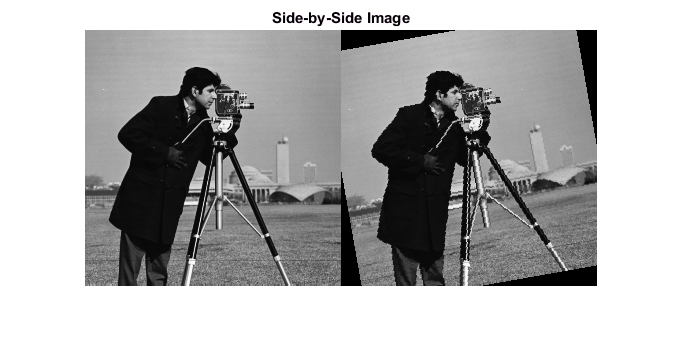

sbs=zeros(max(size(I,1),size(I_t,1)),size(I,2)+size(I_t,2));
sbs(1:size(I,1),1:size(I,2))=I;
sbs(1:size(I_t,1),size(I,2)+1:end)=I_t;

figure,
imshow(sbs)
title('Side-by-Side Image')

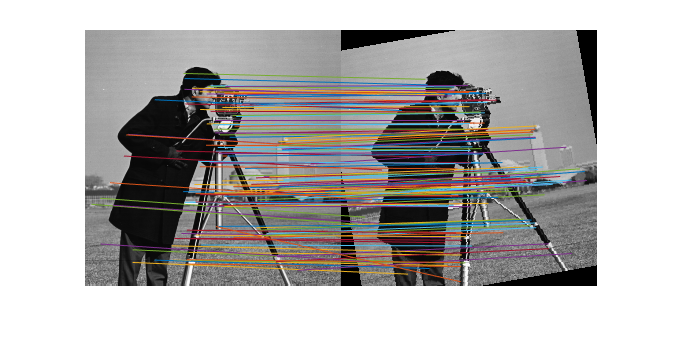


D=pairwise_distance(F,F_t);
P=paired_keypoints(D,0.6);

figure,
imshow(sbs)
hold on
Angle=nan(numel(find(P~=0)),1);
for i=1:numel(P)
   if P(i)~=0
      plot([xyso(i,2),xyso_t(P(i),2)+size(I,2)],[xyso(i,1),xyso_t(P(i),1)])
   end
end

There are some obvious outliers. But in total I think SIFT keypoints are well matched.